## Housekeeping

clc
clear
load("Data/lat_derivatives.mat");
% Everything will be in SI unit
load("Data/long_derivatives.mat");

q = 0.5*flight.rho*flight.U_e^2;

## Lateral stability

% Stability derivatives
%%%%%%%%%%%%%%%%%%%% Regarding side force Y %%%%%%%%%%%%%%%%%%%%
Y_beta = (q*ps.S/mass.m) * lat.C_Y_beta;
Y_p = (q*ps.S/mass.m) * lat.C_Y_p;
Y_r = (q*ps.S/mass.m) * lat.C_Y_r;

%%%%%%%%%%%%%%%%%%%% Regarding rolling moment L %%%%%%%%%%%%%%%%%%%%
L_beta = (q*ps.S*ps.b/mass.Ixx) * lat.C_l_beta;
L_p = (q*ps.S*ps.b/mass.Ixx) * lat.C_l_p;
L_r = (q*ps.S*ps.b/mass.Ixx) * lat.C_l_r;

%%%%%%%%%%%%%%%%%%%% Regarding yawing moment N %%%%%%%%%%%%%%%%%%%%
N_beta = (q*ps.S*ps.b/mass.Izz) * lat.C_n_beta;
N_p = (q*ps.S*ps.b/mass.Izz) * lat.C_n_p;
N_r = (q*ps.S*ps.b/mass.Izz) * lat.C_n_r;

%%%%%%%%%%%%%%%%%%%% C_latontrol derivatives %%%%%%%%%%%%%%%%%%%%
Y_delta_da = q*ps.S/mass.m*ctr.C_y_da;
Y_delta_dr = q*ps.S/mass.m*ctr.C_y_dr;

L_delta_da = q*ps.S*ps.b/mass.Ixx*ctr.C_l_da ;
L_delta_dr = q*ps.S*ps.b/mass.Ixx*ctr.C_l_dr;

N_delta_da = q*ps.S*ps.b/mass.Izz*ctr.C_n_da;
N_delta_dr = q*ps.S*ps.b/mass.Izz*ctr.C_n_dr;

% State matrix A_lat
A_lat = zeros(4) ;
A_lat(1,1) = Y_beta/flight.U_e;
A_lat(1,2) = Y_p/flight.U_e;
A_lat(1,3) = Y_r/flight.U_e-1;
A_lat(1,4) = flight.g*cos(flight.theta_0)/flight.U_e;
A_lat(2,1) = L_beta;
A_lat(2,2) = L_p ;
A_lat(2,3) = L_r;
A_lat(2,4) = 0;
A_lat(3,1) = N_beta;
A_lat(3,2) = N_p;
A_lat(3,3) = N_r;
A_lat(3,4) = 0;
A_lat(4,1) = 0;
A_lat(4,2) = 1;
A_lat(4,3) = 0;
A_lat(4,4) = 0;
eigs_lat = eigs(A_lat);
disp(eigs_lat);
disp(A_lat);

 -32.6439 + 0.0000i
  -0.3838 + 0.7928i
  -0.3838 - 0.7928i
   0.0072 + 0.0000i



    0.0589    0.0124   -0.8624    0.0695
   -0.6276  -32.6057    3.2953         0
    0.9569    0.3732   -0.8576         0
         0    1.0000         0         0



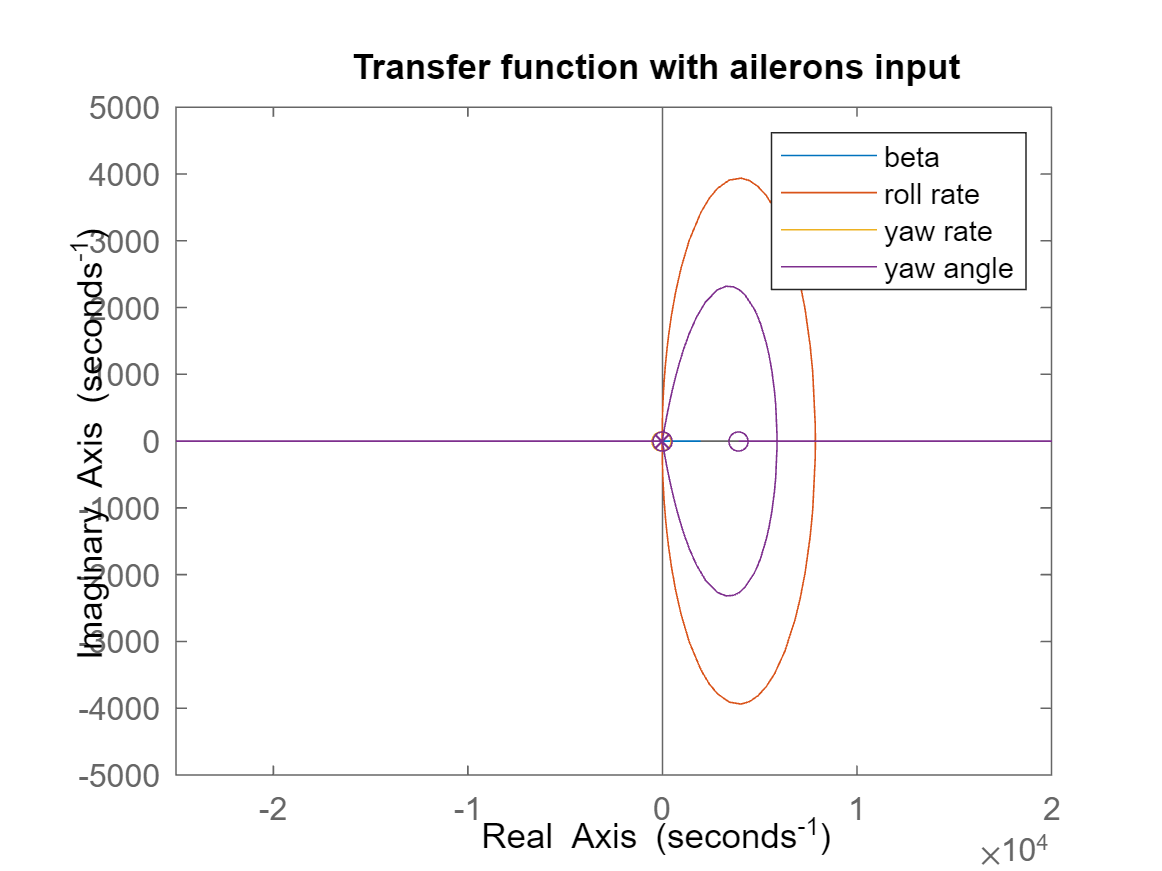



% Control matrix B_lat
B_lat = zeros(4,2);
B_lat(1,1) = Y_delta_da/flight.U_e;
B_lat(1,2) = Y_delta_dr/flight.U_e;
B_lat(2,1) = L_delta_da;
B_lat(2,2) = L_delta_dr;
B_lat(3,1) = N_delta_da;
B_lat(3,2) = N_delta_dr;
B_lat(4,1) = 0;
B_lat(4,2) = 0;


% Output C_lat
C_lat = eye(length(A_lat));

% Feedback matrix D_lat
D_lat = zeros(size(B_lat));

% Open loop analysis
sys_lat_open = ss(A_lat,B_lat,C_lat,D_lat);
%  % Eigenvalue analysis of the open loop system
% tf_lat_open = tf(sys_lat_open);
% % A_latileron input 
% rlocus(tf_lat_open(1,1),tf_lat_open(2,1),tf_lat_open(3,1),tf_lat_open(4,1));
% title("Transfer function with ailerons input")
% legend(["beta","roll rate","yaw rate","yaw angle"])

## Longitudinal stability

% State matrix A_Long
A_long = zeros(4) ;
A_long(1,1) = 1/mass.m * long.X_u;
A_long(1,2) = 1/mass.m * long.X_w;
A_long(1,3) = 1/mass.m * long.X_q;
A_long(1,4) = -flight.g*cos(flight.theta_0);
A_long(2,1) = 1/mass.m * long.Z_u;
A_long(2,2) = 1/mass.m * long.Z_w;
A_long(2,3) = flight.U_e+1/mass.m *long.Z_q;
A_long(2,4) = -flight.g*sin(flight.theta_0);
A_long(3,1) = 1/mass.Iyy * long.M_u;
A_long(3,2) = 1/mass.Iyy * long.M_w;
A_long(3,3) = 1/mass.Iyy * long.M_q;
A_long(3,4) = 0;
A_long(4,1) = 0;
A_long(4,2) = 0;
A_long(4,3) = 1;
A_long(4,4) = 0;
eigs_long = eigs(A_long);
disp(eigs_long);
disp(A_long);


   1.0e+02 *

  -2.5263 + 0.0000i
  -0.0003 + 0.0007i
  -0.0003 - 0.0007i
   0.0000 + 0.0000i



 -252.6348         0         0   -9.8100
         0    0.1062  139.7389         0
         0   -0.0002   -0.1653         0
         0    1.0000         0         0



% Control matrix B_Long
B_long = zeros(4,1);
B_long(1,1) = flight.rho*ps.S*flight.U_e^2/(2*mass.m) * (-scd.C_D_ih);
B_long(2,1) = flight.rho*ps.S*flight.U_e^2/(2*mass.m) * (-scd.C_L_ih);
B_long(3,1) = flight.rho*ps.S*flight.U_e^2*ps.c_bar/(2*mass.Iyy) * (-scd.C_M_ih);
B_long(4,1) = 0;

% Output C_lat
C_long = eye(length(A_long));

% Feedback matrix D_lat
D_long = zeros(size(B_long));

% Open loop analysis
sys_long_open = ss(A_long,B_long,C_long,D_long);

% tf_long_open = tf(sys_long_open);
% % Elevator input 
% rlocus(tf_long_open(1,1),tf_long_open(2,1),tf_long_open(3,1),tf_long_open(4,1));
% title("Transfer function with elevators input")
% legend(["beta","roll rate","yaw rate","yaw angle"])

## Lateral open loop response

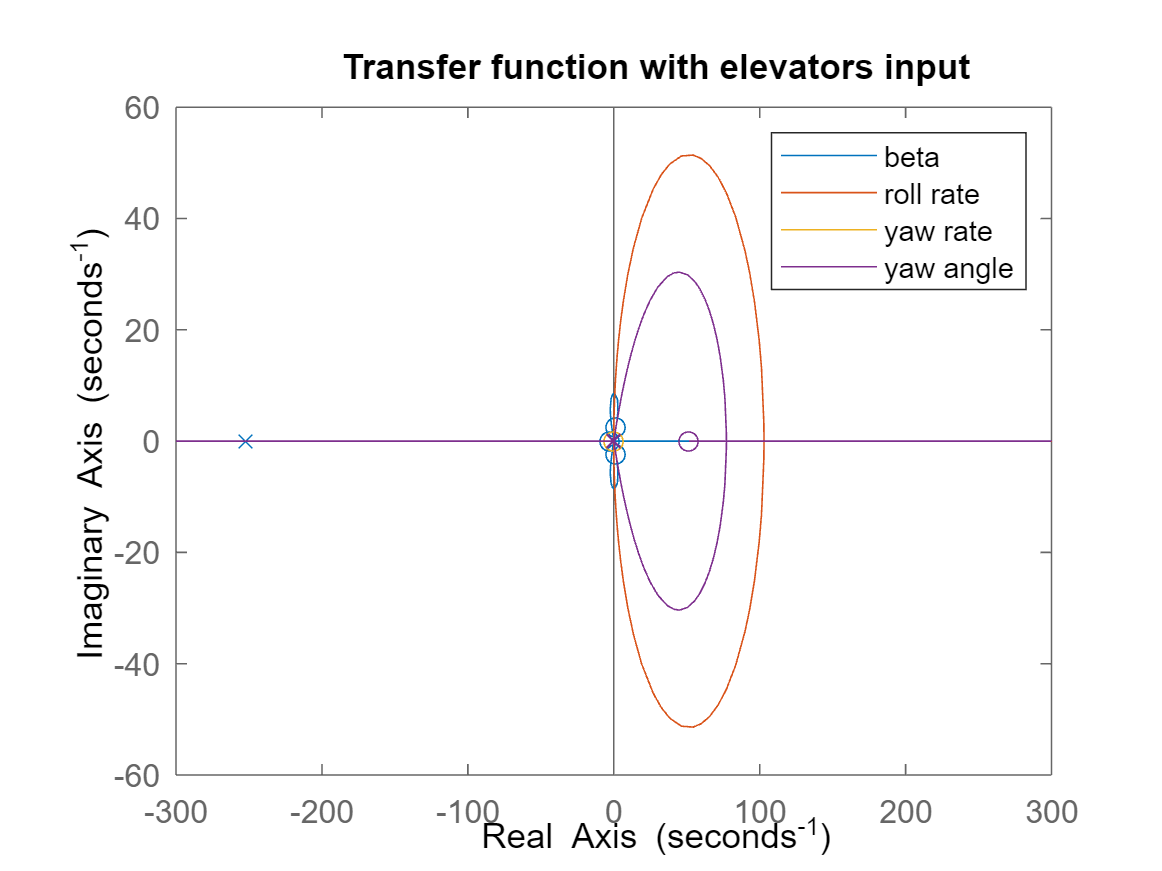

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Pole diagram %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(69);
plt.reference_lat = eigs_lat(2);
plt.slope_lat = abs(imag(plt.reference_lat)/real(plt.reference_lat));
plt.x1_lat = real(plt.reference_lat):0.01:0;
plt.y1_lat = -plt.slope_lat*plt.x1_lat;
plt.y2_lat = abs(imag(plt.reference_lat))*ones(size(plt.x1_lat));

plot(eigs_lat(2:4),"x","MarkerSize",16,"LineWidth",4,"MarkerEdgeColor","k");
hold on
patch([plt.x1_lat fliplr(plt.x1_lat)],[plt.y1_lat fliplr(plt.y2_lat)],"r");
hold on
patch([plt.x1_lat fliplr(plt.x1_lat)],[-plt.y1_lat fliplr(-plt.y2_lat)],"r");
hold on
plt.x3_lat = 0:0.01:1.08;
plt.y3_lat = abs(imag(plt.reference_lat))*ones(size(plt.x3_lat));
patch([plt.x3_lat fliplr(plt.x3_lat)],[plt.y3_lat fliplr(-plt.y3_lat)],"r");
hold on;
plt.t_lat = linspace(0, 2*pi);
plt.r_lat = abs(plt.reference_lat);
plt.x_lat = plt.r_lat*cos(plt.t_lat);
plt.y_lat = plt.r_lat*sin(plt.t_lat);
patch(plt.x_lat, plt.y_lat, 'o')
hold on;
alpha(0.2);
% plot
xlim([-0.5,0]);
ylim([-abs(imag(plt.reference_lat)),abs(imag(plt.reference_lat))]);
xlabel("Real axis")
ylabel("Imaginary axis")
title("Poles of lateral stability")
legend(["Cruise poles","Damping ratio","","","Natural frequency"])
axis equal

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Gramian matrix %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
reachable = isReach(A_lat,B_lat);
display(reachable)

Wc = gram(sys_lat_open,"c");
display(Wc);

[V_lat,D_lat] = eig(Wc);
disp(D_lat);
[~, indices] = sort(diag(D_lat), 'ascend');
projection_matrix_lat = V_lat(:, indices(1:3));

[X_lat, Y_lat, Z_lat] = sphere(50);
a_lat = sqrt(diag(D_lat(indices(1:3), indices(1:3))));
b_lat = projection_matrix_lat * diag(a_lat);
x_lat = b_lat(1, 1) * X_lat;
y_lat = b_lat(2, 2) * Y_lat;
z_lat = b_lat(3, 3) * Z_lat;

figure(70);
cgm_lat = surf(x_lat, y_lat, z_lat);
set(cgm_lat,'edgecolor','none');
xlabel("Principal axis 1");
ylabel("Principal axis 2");
zlabel("Principal axis 3");

function [reachable] = isReach(A,B)
    n_B = size(B,1);

    % construct reachability matrix
    W_r = B;
    for i = 2:n_B
        W_r = [W_r, A^(i-1)*B];
    end

    if rank(W_r) == n_B
        reachable = true;
    else
        reachable = false;
    end

end % of function - remember to leave this here

## All root locus plot

% function [] = rlocus_all(tf_matrix)
% 
%     n = size(tf_matrix,1);
%     m = size(tf_matrix,2);
% 
%     axis off
% 
%     for i = 1:n
%         for j= 1:m
% %             subplot(4,2,(i-1)*m+j);
% %             hold on;
%             figure(69)
%             rlocus(tf_matrix(i,j));
%         end
% %         hold off
%     end
% 
% end

% Root locus plot example
% a = tf(1,[4,5,1,2])
% b = tf([2,3],[4,5,1,2])
% c = tf([3,1,3],[4,5,1,2])
% 
% rlocus(a,b,c)
% legend(["a","b","c"])
% rlocus(c)

% % State matrix A_Long
% A_long = zeros(4) ;
% A_long(1,1) = long.X_u;
% A_long(1,2) = 0;
% A_long(1,3) = 0;
% A_long(1,4) = -flight.g;
% A_long(2,1) = 0;
% A_long(2,2) = 1/mass.m * long.Z_w;
% A_long(2,3) = flight.U_e + 1/mass.m *long.Z_q;
% A_long(2,4) = 0;
% A_long(3,1) = 0;
% A_long(3,2) = 1/mass.Iyy * long.M_w;
% A_long(3,3) = 1/mass.Iyy * long.M_q;
% A_long(3,4) = 0;
% A_long(4,1) = 0;
% A_long(4,2) = 0;
% A_long(4,3) = 1;
% A_long(4,4) = 0;